% - - - - - - - - TERNARY U-N-O PHASE STABILITY PLOTS - - - - - - - - 

%     _______                                 _____  _                      _____  _                                    _____                           _             
%    |__   __|                               |  __ \| |                    |  __ \(_)                                  / ____|                         | |            
%       | | ___ _ __ _ __   __ _ _ __ _   _  | |__) | |__   __ _ ___  ___  | |  | |_  __ _  __ _ _ __ __ _ _ __ ___   | |  __  ___ _ __   ___ _ __ __ _| |_ ___  _ __ 
%       | |/ _ \ '__| '_ \ / _` | '__| | | | |  ___/| '_ \ / _` / __|/ _ \ | |  | | |/ _` |/ _` | '__/ _` | '_ ` _ \  | | |_ |/ _ \ '_ \ / _ \ '__/ _` | __/ _ \| '__|
%       | |  __/ |  | | | | (_| | |  | |_| | | |    | | | | (_| \__ \  __/ | |__| | | (_| | (_| | | | (_| | | | | | | | |__| |  __/ | | |  __/ | | (_| | || (_) | |   
%       |_|\___|_|  |_| |_|\__,_|_|   \__, | |_|    |_| |_|\__,_|___/\___| |_____/|_|\__,_|\__, |_|  \__,_|_| |_| |_|  \_____|\___|_| |_|\___|_|  \__,_|\__\___/|_|   
%                                      __/ |                                                __/ |                                                                     
%                                     |___/                                                |___/                                                                      

% ! ! ! ! ! ! ! SUSPECTED ISSUES ! ! ! ! ! ! ! 
% I am gtting some results with teh wrong number of atoms!
% this is probably form move of binary -> ternary and there are duplicate
% entries for the right and wrong num of atoms.
% howecer we still get the same predicted Ef


%global metal 
%metal = 'U';

tic
% importing data - - - - - - - - -
training_data = readtable("data/targets_extra-cols.csv");    % data used to train the models
nn_data = readtable("data/data_ternaryUNO-NN.csv");          % Neural Network Predictions
nn_data = unique([nn_data(:,"formula"),nn_data(:,"Ef")]);       % triming down unnescesary cols cols and removing dupe rows
rf_data = readtable("data/data_ternaryUNO-RF.csv");          % Random Forrest Predictions
rf_data = unique([rf_data(:,"formula"),rf_data(:,"Ef")]);
nnrf_data = readtable("data/data_ternaryUNO-NNRF.csv");        % Ensemble model Predictions (NN & RF)
nnrf_data = unique([nnrf_data(:,"formula"),nnrf_data(:,"Ef")]);


% for this we will need the 'ternary_plots' feature from MATLAB File Exchange
% https://uk.mathworks.com/matlabcentral/fileexchange/93245-ternary_plots?s_tid=srchtitle_site_search_2_ternary+plots
% stored upstream in this file path on this device
% > ./../../matlab-ternary-plots/

% need to import the data to go along the O-N Axis on the ternary plot.
% From OQMD There exist 4 stable hpases along the N-O axis
% N - NO2 - N2O5 - O We will assime that if needed the table will be able
% to predict all, and only the found phases.


% we also need to change how the U and O fractions are calculated. as the
% orthogonal axis were unable to describe the full ternary space.



nnrf_post = 132×3 table
                   nfrac      ofrac      Ef_eV  
                  _______    _______    ________

    U(N2O)2           0.8    0.66667    -0.76215
    U(N4O3)2      0.88889    0.85714    -0.81841
    U(NO)2        0.66667    0.66667     -1.2853
    U(NO)3           0.75       0.75     -1.0465
    U(NO)4            0.8        0.8    -0.94072
    U(NO2)2       0.66667        0.8     -1.3116
    U11(N3O2)6    0.62069    0.52174     -1.0406
    U2(NO)3           0.6        0.6     -1.4454
    U2N           0.33333          0    -0.49241
    U2N25         0.92593          0    -0.42313
    U2N2O             0.5    0.33333     -1.8961
    U2N2O3            0.5       

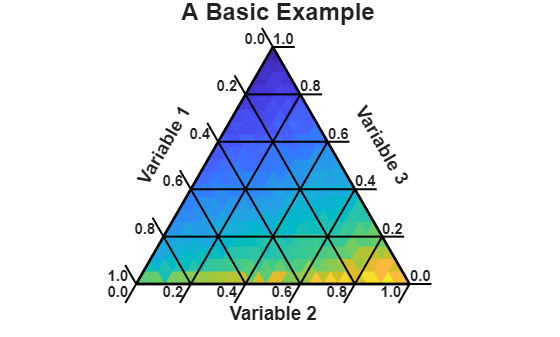

Invalid or deleted object.

Error in restack_dataplots (line 66)
        elseif ( strcmp( dataplots(i).object.Type , 'patch'  )==1 )
        ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^















addpath('../../matlab-ternary-plots/')
add_ternary_paths

% example of ternary plot

f = figure;

 handle_base  = ternary_axes; 
    
% (3) Get a set of A,B,C Test points, assuming 20 points along each side
    [A,B,C] = ternary_arrays( 20 );
    
% (5) Create example data
    Z = (A+10)*2.0 + 10*B.^1.2 - 5*sqrt(C*5);
    
% (6) Plot the surface Z defiend on rows of ABC points in xmat
    
    % Create Surface Plot
    dataplots(1).obj = ternary_surf( [], 'l', A, 'b', B, Z ,'none');
    
    % Add Title
    title('A Basic Example','FontSize',18)
    
% (7) Restack Data Plots
    handle_base = restack_dataplots(handle_base, dataplots);